# Compile Figures 

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


%What is your project name?
ProjFolder = 'CB_thawingdepth_disturbed/';

%do you want the figure saved?
printfig  = true;

%Where do you want to save files?
workdirfig = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed/figures/stbALD';

%Where is your data?
workdir = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed/';



Lets plot the results

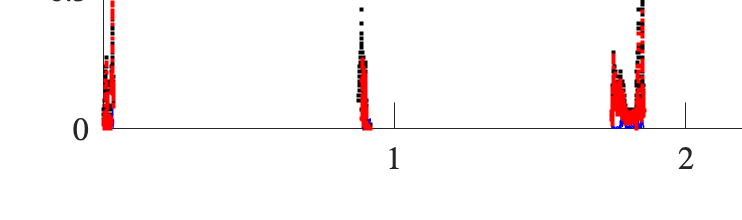

f3 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 21.6500 6.4000]
       Units: 'inches'

  Show all properties


% % %Plot time with discharge and precipitation. This function will change
% % %depending on data format. Please change this function accordingly
% % origdat=char(strcat(originaldata(1)));
% % f1 = figtQP_plot_UK(origdat,workdir,workdirfig,printfig)

cd(workdir)
%Plot ERRA time with real discharge, predicted discharge, and its residual
f3 = figtQQp_plot_dZ(workdir,workdirfig,printfig,2)

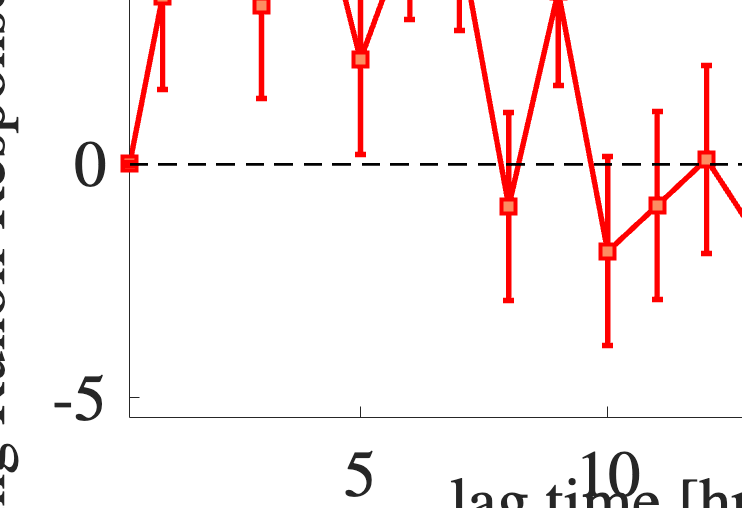

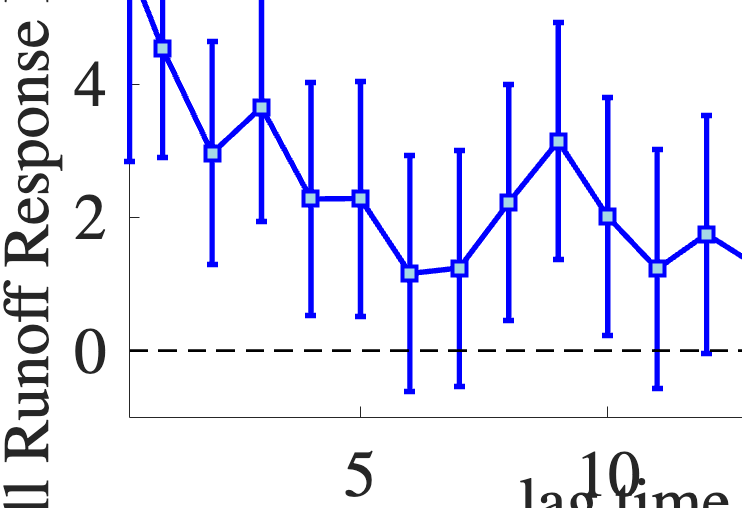

f4 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 9.3500 6.4000]
       Units: 'inches'

  Show all properties


cd(workdir)
%Plot lagtime with RRD
str = {'Rresults_stbALD/1hr_simple_RRD.txt'};
f4 = figtRRD_plot_dZ('Ptarmigan, Melville Island (NU) Disturbed; Q',workdir,workdirfig,printfig,2,str)